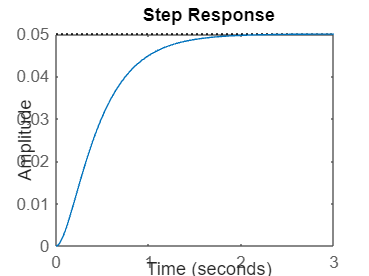

clc;
clear;
close all;

%transfer function
m = 1;
b = 10;
k = 20;
F = 1;
s = tf('s');
P = 1/(s^2 + 10*s + 20);
figure(1);
%step response without controller
figure(1);
step(P);

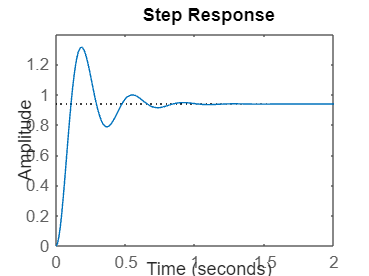

%step response with p-controller
Kp = 300;
C = pid(Kp);
T = feedback(C*P,1);
t = 0:0.01:2;
figure(2);
step(T,t);

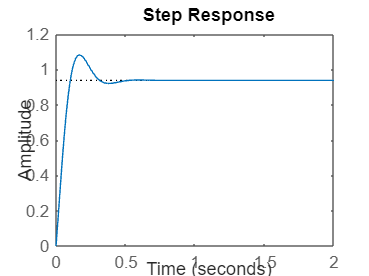


%step response with pd-controller
Kp = 300;
Kd = 10;
C = pid(Kp,0,Kd);
T = feedback(C*P,1);
t = 0:0.01:2;
figure(3);
step(T,t);

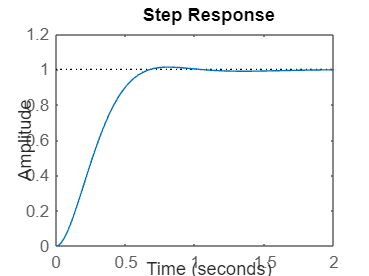


%step response with pi-controller
Kp = 30;
Ki = 70;
C = pid(Kp,Ki);
T = feedback(C*P,1);
t = 0:0.01:2;
figure(4);
step(T,t);

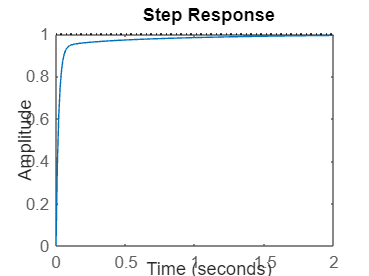


%step response with pid1-controller
Kp = 350;
Ki = 300;
Kd = 50;
C = pid(Kp,Ki,Kd);
T = feedback(C*P,1);
t = 0:0.01:2;
figure(5);
step(T,t);



%pid tuner
pidTuner(P,'p');
pidTuner(P,C);
opts = pidtuneOptions('CrossoverFrequency',32,'PhaseMargin',90);
[C, info] = pidtune(P, 'pid', opts);